# Bode Plot

Sketch the Bode Plot of following transfer function 


$$G\left(s\right)H\left(s\right)=\frac{K}{s\left(s+2\right)\left(s+100\right)}$$


Determine the gain and phase crossover frequency along with Gain and phase margin for K = 2000;

## Define Transfer function 

K = 1200;
GH = tf(K, [1 102 200 0])

GH =
 
          1200
  ---------------------
  s^3 + 102 s^2 + 200 s
 
Continuous-time transfer function.
Model Properties


## Draw Bode plot

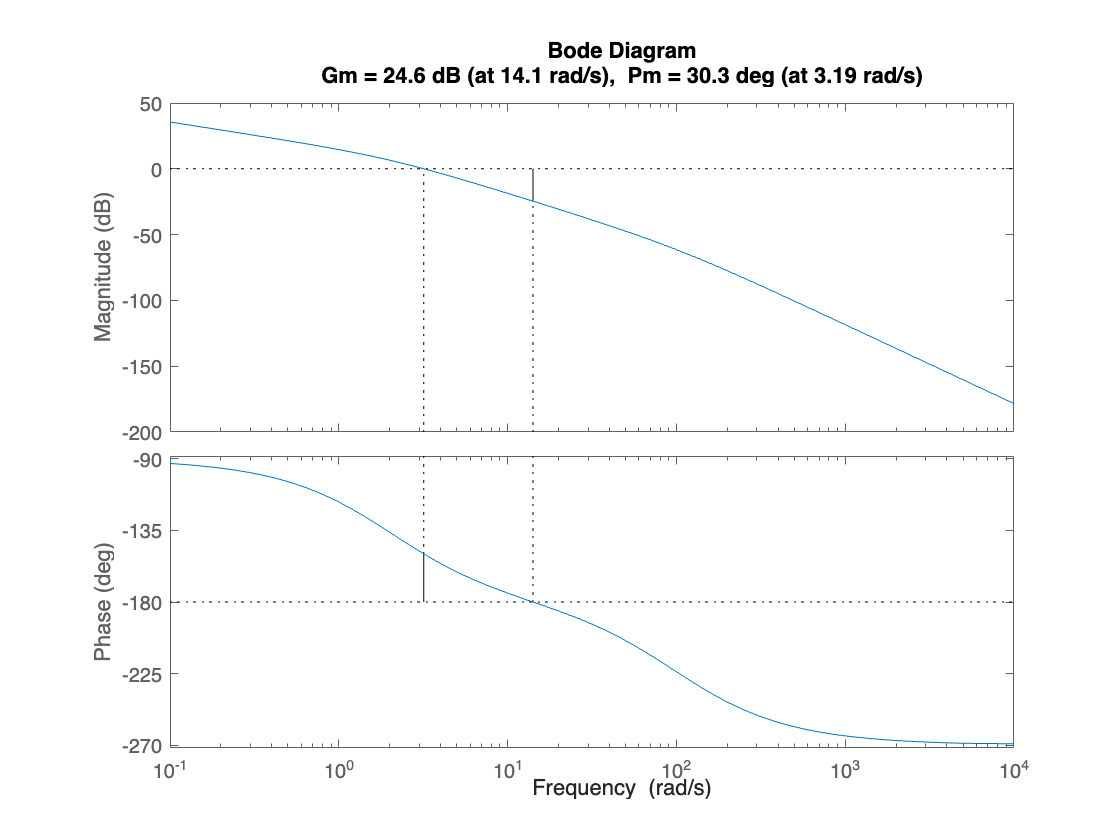

%bode(GH)
margin(GH)

## Frequency domin specifications 

[gm, pm, wcg, wcp] = margin(GH);    % gm = Gain margin, pm = Phase margin
                                     % wcg = Gain crossover freq, wcp = Phase crossover freq

% Display results
disp('Bode Plot Analysis:');

Bode Plot Analysis:


disp(['Gain Margin (dB): ', num2str(20*log10(gm)), ' dB']);

Gain Margin (dB): 24.609 dB


disp(['Phase Margin (deg): ', num2str(pm), ' degrees']);

Phase Margin (deg): 30.2815 degrees


disp(['Gain Crossover Frequency (rad/s): ', num2str(wcg)]);

Gain Crossover Frequency (rad/s): 14.1421


disp(['Phase Crossover Frequency (rad/s): ', num2str(wcp)]);

Phase Crossover Frequency (rad/s): 3.1874
